Load data

china=preprocess('data/china.csv');
korea=preprocess('data/korea.csv');
taiwan=preprocess('data/taiwan.csv');

Rsiduals visualization      

%======CHINA=====
[tr,y_tr,te,y_te] = train_test_split(china);
[beta,stats] = ols(tr,y_tr)

stats = struct with no fields.


stats = struct with fields:
    sigma2: 357.0880


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401
            R2: 0.9991


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401
            R2: 0.9991
        adj_R2: 0.9985


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401
            R2: 0.9991
        adj_R2: 0.9985
            SE: [18×1 double]
     residuals: [40×1 double]


beta = 	1.0e+04 *

   -2.9712
    0.0024
    0.0097
   -0.0160
   -0.0037
   -0.0180
    0.0001
   -0.0230
    0.0027
   -0.0026


stats = struct with fields:
              sigma2: 357.0880
          sample_var: [18×18 double]
           std_error: [18×1 double]
                 AIC: 6.1801
                 BIC: 6.9401
                  R2: 0.9991
              adj_R2: 0.9985
                  CI: [18×2 double]
            p_values: NaN
    significant_test: 1
           residuals: [40×1 double]


[result] = test_model(beta,tr,y_tr);

result = struct with no fields.


result = struct with fields:
    residuals: [40×1 double]
          SSE: 7.8559e+03
          SST: 9.1345e+06


result = struct with fields:
    residuals: [40×1 double]
          SSE: 7.8559e+03
          SST: 9.1345e+06
           R2: 0.9991


x = 1:1:size(tr)

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40


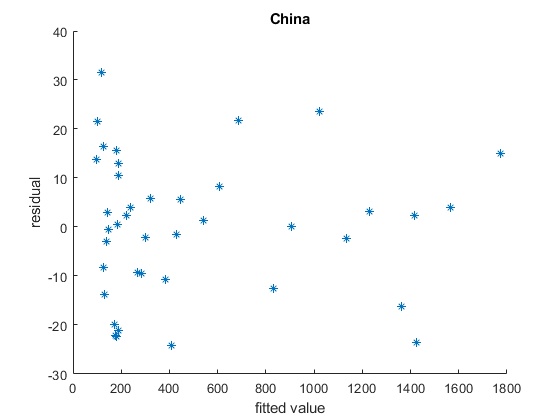

scatter(result.y_hat,result.residuals,'*')
ylabel('residual') 
xlabel('fitted value') 
title('China')

Breusch Pagan Test

[BP_stat,BP_crit,H] = Breusch_Pagan_test(tr,result.residuals,0.95)

n = 40

p = 18

g =    85.1883
   29.2935
   85.4394
  207.0252
    2.8972
    3.0445
  223.6638
  446.2467
  176.8786
  120.0757


gamma = 	1.0e+05 *

   -1.0266
    0.0005
   -0.0010
    0.0005
   -0.0003
    0.0002
   -0.0012
    0.0008
   -0.0005
    0.0010


g_hat =    75.9818
  100.3705
  145.5406
   55.6707
   69.3446
   69.9514
  132.7621
  365.3556
  277.0259
   60.6992


BP_stat = 2.5995e+05

BP_crit = 9.3905

H = 1

BP_stat = 2.5995e+05

BP_crit = 9.3905

H = 1

FSL

[tr]=standardize(tr)

tr =     1.0000   -1.6680   -0.4700    1.7848    1.4935   -1.9460   -0.0932   -1.2700   -0.2789   -1.6533   -1.6457   -0.8067   -0.7558   -1.5335   -0.1230    0.7742    0.0842    0.9991
    1.0000   -1.5825   -0.4277    1.4706    1.1313   -1.4954   -0.0932   -1.1650    0.0969   -1.2338   -1.3080   -0.7945   -0.8472   -1.4672    0.4342    1.3384    0.6125    0.9751
    1.0000   -1.4969   -0.3154    1.4684    1.2957   -1.1009   -0.0932   -1.5941   -1.0841   -0.9942   -1.0668   -0.6690   -0.7701   -1.3897    0.4525    1.2705    0.6935    1.0529
    1.0000   -1.4114   -0.3916    1.5267    1.4343   -1.4981   -0.0932   -1.2691   -0.5637   -1.2456   -1.2717   -0.7842   -0.8577   -1.3123    0.4407    1.1110    0.5970    1.0266
    1.0000   -1.3259    0.0068    1.2971    1.1801   -1.0226   -0.0932   -1.3531   -0.9371   -1.0678   -1.1680   -0.5921   -0.7242   -1.2460    0.4720    1.0639    0.6199    0.8727
    1.0000   -1.2403    0.1379    1.2297    1.1943   -0.8569   -0.0932   -1.4064   -1.1796

[beta,stats_FGLS] = FGLS(tr,y_tr)  

stats = struct with no fields.


stats = struct with fields:
    sigma2: 357.0880


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401
            R2: 0.9991


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401
            R2: 0.9991
        adj_R2: 0.9985


stats = struct with fields:
        sigma2: 357.0880
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.1801
           BIC: 6.9401
            R2: 0.9991
        adj_R2: 0.9985
            SE: [18×1 double]
     residuals: [40×1 double]


stats = struct with no fields.


stats = struct with fields:
    sigma2: 378.9783


stats = struct with fields:
        sigma2: 378.9783
    sample_var: [18×18 double]


stats = struct with fields:
        sigma2: 378.9783
    sample_var: [18×18 double]
     std_error: [18×1 double]


stats = struct with fields:
        sigma2: 378.9783
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.2396


stats = struct with fields:
        sigma2: 378.9783
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.2396
           BIC: 6.9996


stats = struct with fields:
        sigma2: 378.9783
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.2396
           BIC: 6.9996
            R2: 0.9991


stats = struct with fields:
        sigma2: 378.9783
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.2396
           BIC: 6.9996
            R2: 0.9991
        adj_R2: 0.9984


stats = struct with fields:
        sigma2: 378.9783
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.2396
           BIC: 6.9996
            R2: 0.9991
        adj_R2: 0.9984
            SE: [18×1 double]
     residuals: [40×1 double]


beta = 	1.0e+03 *

    0.5102
    0.2567
    0.0818
    1.5580
   -0.2121
    0.8024
    0.0036
    0.5285
    0.0573
   -0.0819


stats_FGLS = struct with fields:
        sigma2: 378.9783
    sample_var: [18×18 double]
     std_error: [18×1 double]
           AIC: 6.2396
           BIC: 6.9996
            R2: 0.9991
        adj_R2: 0.9984
            SE: [18×1 double]
     residuals: [40×1 double]


Breush Pagan on FGLS

[BP_stat,BP_crit,H] = Breusch_Pagan_test(tr,stats_FGLS.residuals,0.95)

n = 40

p = 18

g =    37.1276
    0.1791
    1.4122
  313.9640
    0.0717
    0.3763
  145.9034
  672.3583
  164.4775
   98.8150


gamma = 	1.0e+06 *

    0.0001
    0.0008
   -0.0001
   -2.6267
   -0.0002
   -1.5111
   -0.0002
   -1.3762
   -0.0000
    0.0001


g_hat =    46.5942
   70.9399
  153.7128
   23.5869
   46.4626
   58.7142
  145.6300
  490.6847
  325.4497
   33.6143


BP_stat = 3.4486e+05

BP_crit = 9.3905

H = 1

BP_stat = 3.4486e+05

BP_crit = 9.3905

H = 1